Initialization

close all
addpath myFunction\myftn
clearvars -except mapCD
fn = 'RawData\1T-TaS2(point defect)\mapCD.mat';
loadif(fn);

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



load RawData\'1T-TaS2(point defect)'\vDos.mat vDos
load RawData\'1T-TaS2(point defect)'\grd.mat

DataProcessing

% xsC = 5;xeC = 551;NC = 43;
% xsA = 9;xeA = 723;NA = 56;
% line_info = [xsC xeC NC;xsA xeA NA]
line_info = grd.line_info(:,:,1)

line_info =      5   551    43
     9   725    56


for iphase = 1:2
    xlns = linspace(line_info(iphase,1),line_info(iphase,2),line_info(iphase,3))
    xlnsHolder{iphase} = round(xlns)
end

xlns =      5    18    31    44    57    70    83    96   109   122   135   148   161   174   187   200   213   226   239   252   265   278   291   304   317   330   343   356   369   382   395   408   421   434   447   460   473   486   499   512   525   538   551


xlnsHolder = 1×1 cell array
    {[5 18 31 44 57 70 83 96 109 122 135 148 161 174 187 200 213 226 239 252 265 278 291 304 317 330 343 356 369 382 395 408 421 434 447 460 473 486 499 512 525 538 551]}


xlns =     9.0000   22.0182   35.0364   48.0545   61.0727   74.0909   87.1091  100.1273  113.1455  126.1636  139.1818  152.2000  165.2182  178.2364  191.2545  204.2727  217.2909  230.3091  243.3273  256.3455  269.3636  282.3818  295.4000  308.4182  321.4364  334.4545  347.4727  360.4909  373.5091  386.5273  399.5455  412.5636  425.5818  438.6000  451.6182  464.6364  477.6545  490.6727  503.6909  516.7091  529.7273  542.7455  555.7636  568.7818  581.8000  594.8182  607.8364  620.8545  633.8727  646.8909


xlnsHolder = 1×2 cell array
    {[5 18 31 44 57 70 83 96 109 122 135 148 161 174 187 200 213 226 239 252 265 278 291 304 317 330 343 356 369 382 395 408 421 434 447 460 473 486 499 512 525 538 551]}    {[9 22 35 48 61 74 87 100 113 126 139 152 165 178 191 204 217 230 243 256 269 282 295 308 321 334 347 360 374 387 400 413 426 439 452 465 478 491 504 517 530 543 556 569 582 595 608 621 634 647 660 673 686 699 712 725]}


## Visualization

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0.1 1 .6]);
f1.Visible = "on";

visualize handle

iPhase = 2

iPhase = 2



Z = mapCD.dt(iPhase).Z;
szy = size(Z,2)

szy = 621

yfcs = 347

yfcs = 347

n_line = line_info(iPhase,3)

n_line = 56

index_line = 23

index_line = 23

tiledlayout(1,2)
nexttile
views(Z)
tmp = xlnsHolder{iPhase}

tmp =      9    22    35    48    61    74    87   100   113   126   139   152   165   178   191   204   217   230   243   256   269   282   295   308   321   334   347   360   374   387   400   413   426   439   452   465   478   491   504   517   530   543   556   569   582   595   608   621   634   647


xFocus = tmp(index_line)

xFocus = 295

xline(xFocus,'r')
colormap(gca(),'gray')
yline(yfcs,'b')
% yticks([])

nexttile
Gcut = mapCD.dt(iPhase).G(xFocus,:,:);
Gcut = squeeze(Gcut);
Gcut = Gcut';
views(Gcut)
axis normal
ax = gca()

ax =   Axes with properties:

             XLim: [0.5000 1.5215e+03]
             YLim: [0.5000 621.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5347 0.1100 0.3958 0.8150]
            Units: 'normalized'

  Show all properties


img = findobj(ax,'Type','image')

img =   Image with properties:

           CData: [621×1521 double]
    CDataMapping: 'scaled'

  Show all properties


img.XData = mapCD.V

img =   Image with properties:

           CData: [621×1521 double]
    CDataMapping: 'scaled'

  Show all properties


xline(0,'w')
xlabel('E (eV)')
colormap(ax,'jet')
yline(yfcs,'--w')
% yticks([]) 
colorbar

bands = [mapCD.dt(iPhase).Gap_n(xFocus,:); mapCD.dt(iPhase).Gap_p(xFocus,:)]

bands =    -0.1450   -0.1500   -0.1550   -0.1590   -0.1620   -0.1630   -0.1630   -0.1630   -0.1630   -0.1630   -0.1620   -0.1620   -0.1610   -0.1610   -0.1620   -0.1670   -0.1710   -0.1760   -0.1790   -0.1800   -0.1810   -0.1810   -0.1810   -0.1800   -0.1800   -0.1790   -0.1790   -0.1800   -0.1810   -0.1830   -0.1900   -0.1960   -0.2010   -0.2040   -0.2050   -0.2060   -0.2060   -0.2040   -0.2020   -0.1990   -0.1950   -0.1930   -0.1920   -0.1910   -0.1920   -0.1920   -0.1930   -0.1950   -0.1950   -0.1960
    0.2300    0.2310    0.2060    0.2020    0.2000    0.1970    0.1940    0.1930    0.1930    0.1930    0.1940    0.1950    0.1950    0.1960    0.1970    0.1980    0.1990    0.1990    0.1990    0.1980    0.1960    0.1950    0.1950    0.1950    0.1940    0.1940    0.1940    0.1940    0.1950    0.1950    0.1970    0.1950    0.1860    0.1820    0.1790    0.1780    0.1770    0.1770    0.1780    0.1800    0.1820    0.1850    0.1910    0.1950    0.1960    0.1980    0.1960    0.1940    0.1890 

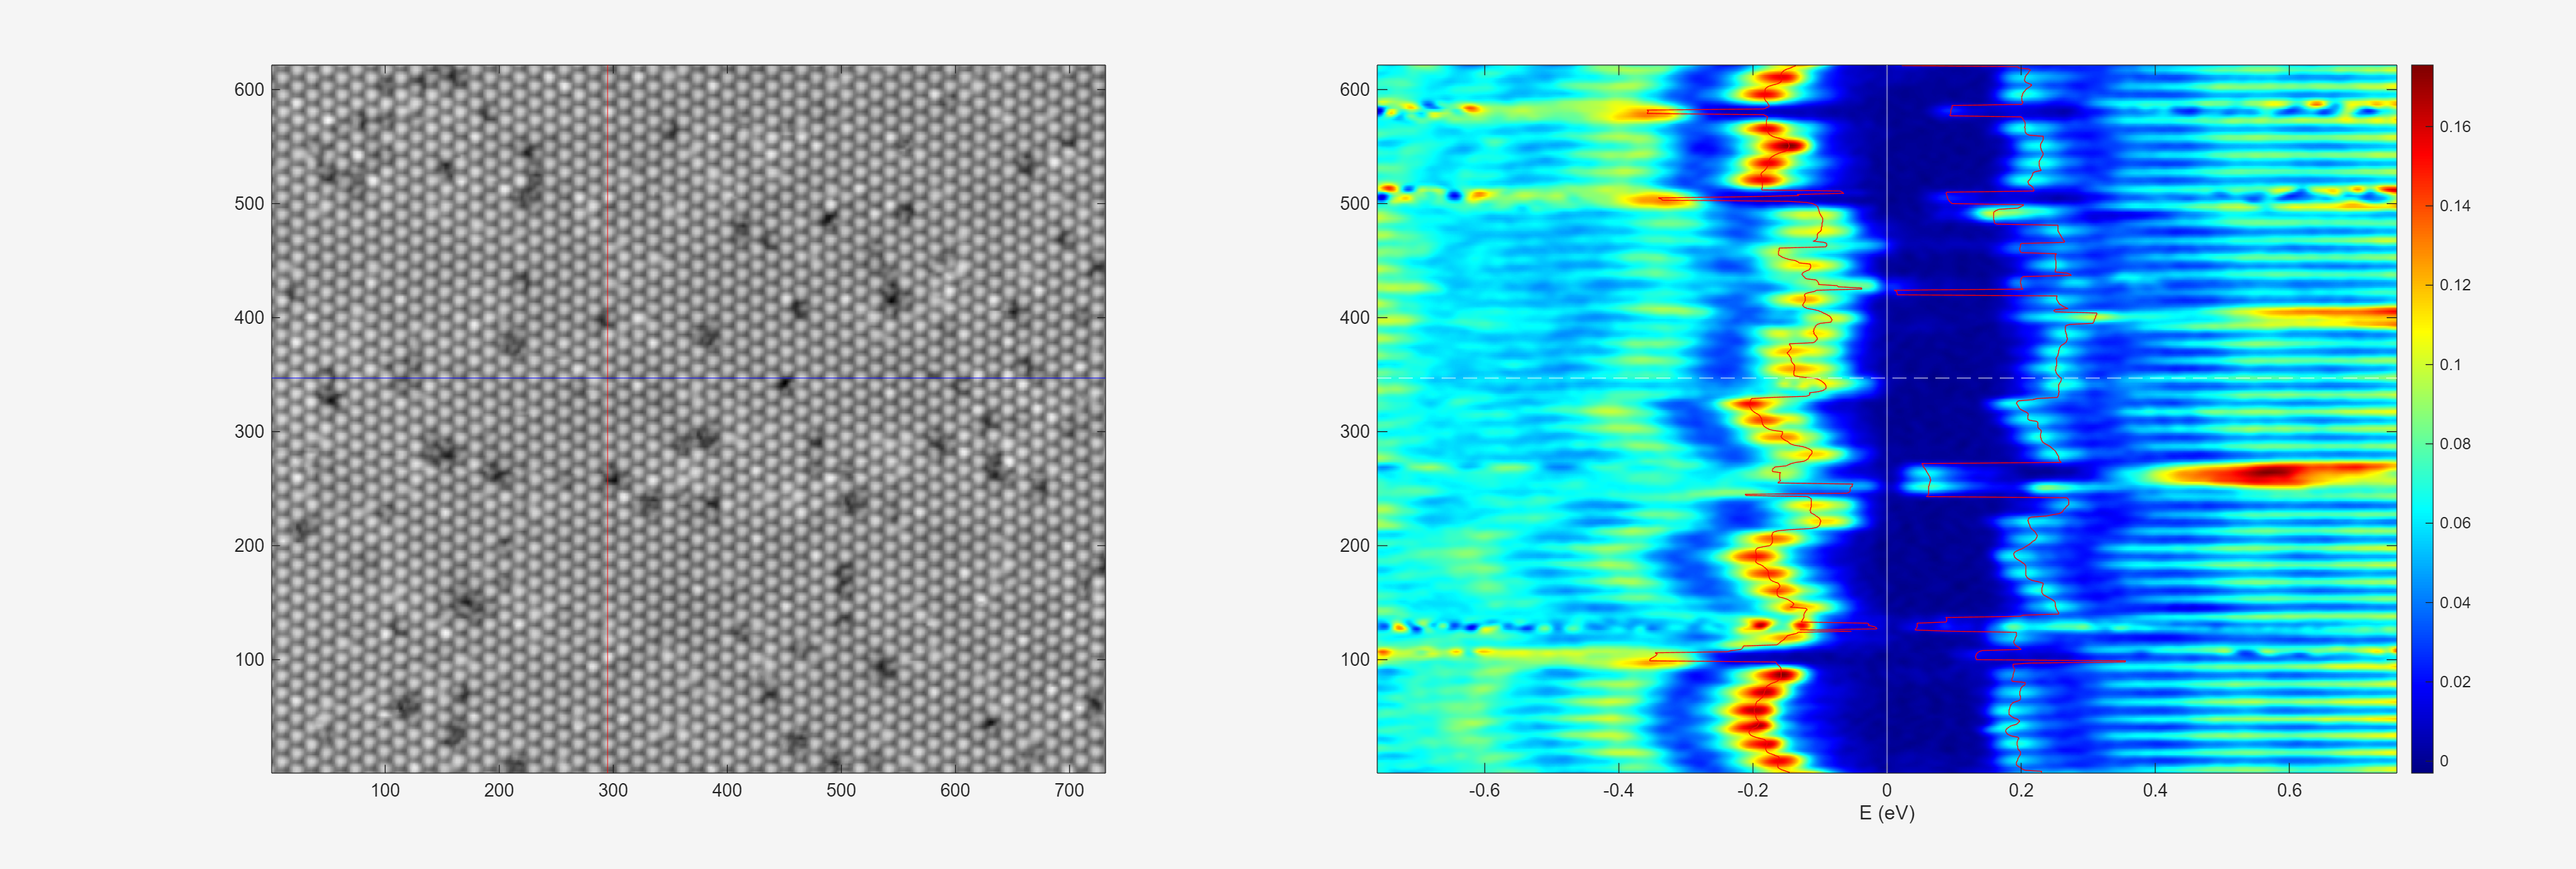

hold on
plot(bands(1,:),1:length(bands),'r')
plot(bands(2,:),1:length(bands),'r')
hold off